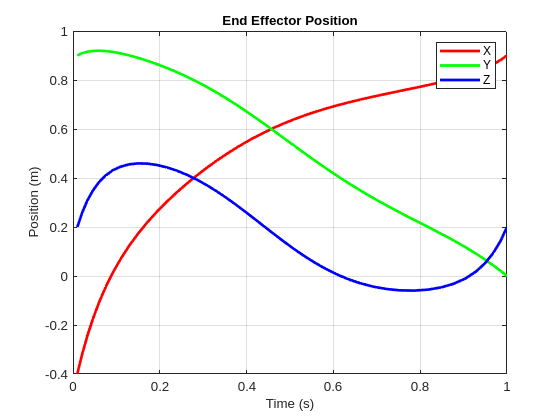

close all;
clear all;
clc;

% Load UR5e robot
robot = loadrobot("universalUR5e");
robot.DataFormat = 'row';

% Add gripper (optional)
ur5e = exampleHelperAddGripper(robot);

% Home position
homePosition = deg2rad([-15, -126, 113, -80, -91, 76]);
for i = 1:6
    ur5e.Bodies{i+2}.Joint.HomePosition = homePosition(i);
end

% Inverse kinematics solver
ik = inverseKinematics('RigidBodyTree', ur5e);
weights = [1, 1, 1, 1, 1, 1];
initialGuess = homePosition;

% Define waypoints with 4 control points
waypoints = [-0.4, 0.4, 0.7, 0.9, ;  % X positions
             0.9, 0.8, 0.4, 0.0, ;  % Y positions
             0.2, 0.4, 0.0, 0.2, ]; % Z positions

% Transpose waypoints to match spline requirements
controlPoints = waypoints';

% Number of samples (interpolated points)
numSamples = 15;

% Perform cubic spline interpolation for each dimension (X, Y, Z)
t = linspace(1, length(controlPoints), length(controlPoints)); % Time vector for control points
tt = linspace(1, length(controlPoints), numSamples * (length(controlPoints) - 1)); % Interpolated time vector

% Generate piecewise polynomials (pp) for each dimension (X, Y, Z)
splineX = spline(t, controlPoints(:, 1));
splineY = spline(t, controlPoints(:, 2));
splineZ = spline(t, controlPoints(:, 3));

% Evaluate the cubic spline at the new interpolated points
splineX_vals = ppval(splineX, tt);
splineY_vals = ppval(splineY, tt);
splineZ_vals = ppval(splineZ, tt);

% Velocity and acceleration (first and second derivatives)
velocityX = ppval(fnder(splineX), tt); % First derivative of X
velocityY = ppval(fnder(splineY), tt); % First derivative of Y
velocityZ = ppval(fnder(splineZ), tt); % First derivative of Z

accelerationX = ppval(fnder(fnder(splineX)), tt); % Second derivative of X
accelerationY = ppval(fnder(fnder(splineY)), tt); % Second derivative of Y
accelerationZ = ppval(fnder(fnder(splineZ)), tt); % Second derivative of Z

% Combine the position, velocity, and acceleration
interpolatedPoints = [splineX_vals', splineY_vals', splineZ_vals'];
velocities = [velocityX', velocityY', velocityZ'];
accelerations = [accelerationX', accelerationY', accelerationZ'];

% velocity based Time vector 
velocities_magnitude = sqrt(velocities(:,1).^2 + velocities(:,2).^2 + velocities(:,3).^2);
time = cumsum(1 ./ velocities_magnitude);
time = time / max(time); % Normalize to [0,1]

% Position plot
f1= figure;
plot(time, interpolatedPoints(:,1), 'r', 'LineWidth', 2); hold on;
plot(time, interpolatedPoints(:,2), 'g', 'LineWidth', 2);
plot(time, interpolatedPoints(:,3), 'b', 'LineWidth', 2);
title('End Effector Position','FontSize',10);
xlabel('Time (s)','FontSize',10);
ylabel('Position (m)','FontSize',10);
legend({'X', 'Y', 'Z'});
grid on;

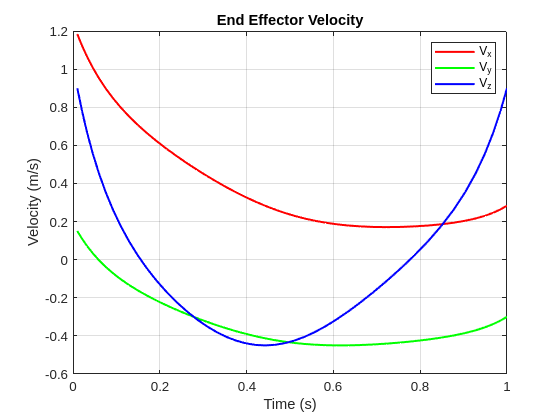

savefig(f1,"cubicp.fig");   % saves the figure  

% Velocity plot (showing X, Y, Z components)
f2= figure;
plot(time, velocities(:,1), 'r', 'LineWidth', 1.5); hold on;
plot(time, velocities(:,2), 'g', 'LineWidth', 1.5);
plot(time, velocities(:,3), 'b', 'LineWidth', 1.5);
title('End Effector Velocity');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
legend({'V_x', 'V_y', 'V_z'});
grid on;

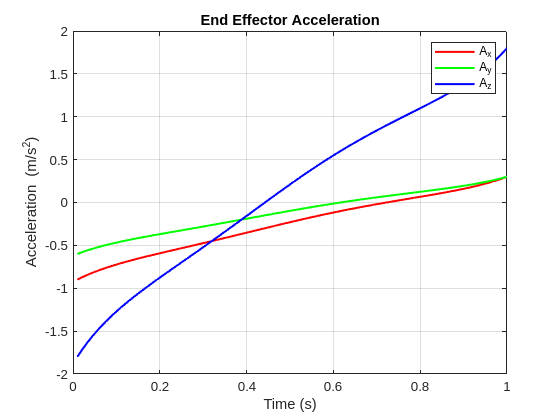

savefig(f2,"cubicv.fig");   % saves the figure  

% Acceleration plot (showing X, Y, Z components)
f3 = figure;
plot(time, accelerations(:,1), 'r', 'LineWidth', 1.5); hold on;
plot(time, accelerations(:,2), 'g', 'LineWidth', 1.5);
plot(time, accelerations(:,3), 'b', 'LineWidth', 1.5);
title('End Effector Acceleration');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
legend({'A_x', 'A_y', 'A_z'});
grid on;

savefig(f3,"cubica.fig");   % saves the figure  


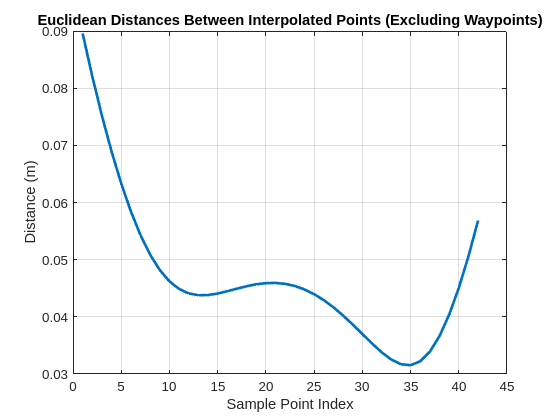

% Exclude waypoints from the interpolated points for distance calculation
excludeControlPoints = false(size(interpolatedPoints, 1), 1);
for i = 1:size(waypoints, 2)
    for j = 1:size(interpolatedPoints, 1)
        % Check if the interpolated point matches the waypoint
        if all(abs(interpolatedPoints(j,:) - waypoints(:, i)') < 1e-6)
            excludeControlPoints(j) = true;  % Mark the waypoint to exclude
            break;
        end
    end
end

% Exclude the waypoints (control points) from the interpolated points
interpolatedPointsWithoutWaypoints = interpolatedPoints(~excludeControlPoints, :);

% Compute Euclidean distances between consecutive interpolated points (excluding waypoints)
numPoints = size(interpolatedPointsWithoutWaypoints, 1);
distances = zeros(numPoints-1, 1); % Preallocate distance array
for i = 1:numPoints-1
    % Compute Euclidean distance between consecutive points
    distances(i) = norm(interpolatedPointsWithoutWaypoints(i+1, :) - interpolatedPointsWithoutWaypoints(i, :));
end

% Plot Euclidean distances between sample points (excluding waypoints)
figure;
plot(1:length(distances), distances, 'LineWidth', 2);
title('Euclidean Distances Between Interpolated Points (Excluding Waypoints)');
xlabel('Sample Point Index');
ylabel('Distance (m)');
grid on;

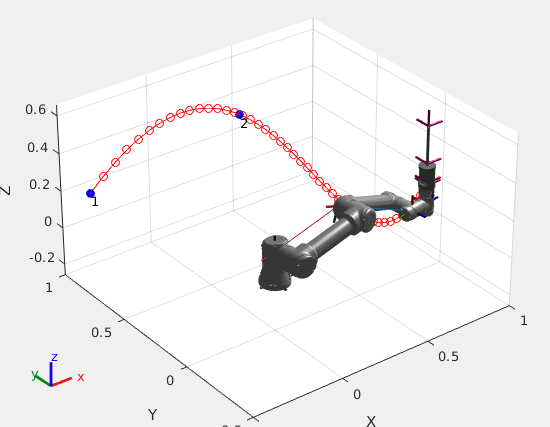

% Visualize the robot's path and waypoints
figure;
show(ur5e, homePosition, 'Frames', 'on', 'PreservePlot', true);
hold on;

% Plot interpolated trajectory
plot3(interpolatedPoints(:, 1), interpolatedPoints(:, 2), interpolatedPoints(:, 3), 'ro-', 'LineWidth', 0.5);

% Plot waypoints (control points)
plot3(waypoints(1,:), waypoints(2,:), waypoints(3,:), 'bo', 'MarkerFaceColor', 'b');

% Add labels
text(waypoints(1,:), waypoints(2,:), waypoints(3,:), {'1','2','3','4'}, 'VerticalAlignment','top','HorizontalAlignment','left');

% Create a VideoWriter object
videoFilename = 'Cubic_spline_animation.avi'; % Output video file name
video = VideoWriter(videoFilename, 'Motion JPEG AVI'); % Choose format (can also be 'MPEG-4')
video.FrameRate = 30; % Set frames per second (FPS)
open(video); % Open the video file

% Set the initial camera angle and axis limits
view(3);  % Set the view to 3D
axis([-0.5 1 -0.5 1 -0.2 0.6]);  % Set axis limits for a clear view
grid on;
axis equal;

% Define dynamic Z axis limits
zMin = -0.2;
zMax = 0.6;

% Your existing code to animate the UR5e robot
for i = 1:size(interpolatedPoints, 1)
    targetPose = trvec2tform(interpolatedPoints(i, :)); % Convert to homogeneous transformation
    [configSol, solInfo] = ik("tool0", targetPose, weights, initialGuess);
    initialGuess = configSol;  % Update the initial guess
    
    % Display the robot configuration
    show(ur5e, configSol, 'PreservePlot', false);
    
    % Update Z axis dynamically based on the robot's current position
    currentZ = interpolatedPoints(i, 3); % Z-coordinate of the robot's end effector
    
    % Adjust Z limits slightly around the current position
    zMin = min(zMin, currentZ - 0.2); % Slight zoom-out in Z
    zMax = max(zMax, currentZ + 0.2); % Slight zoom-out in Z
    
    % Update axis limits dynamically
    axis([-0.5 1 -0.5 1 zMin zMax]);
    
    % Capture the current figure as a frame
    frame = getframe(gcf);  % Capture the frame from the current figure
    writeVideo(video, frame); % Write the captured frame to the video
    
    pause(0.01);  % Pause to control animation speed
end


% Close the video file after finishing the animation
close(video);

disp('Animation saved as Cubic_spline_animation.avi');

Animation saved as Cubic_spline_animation.avi
